# Interpolación de splines cúbicos

%Datos iniciales (ya sea la función f(x) o puntos )

%En este caso lo resolveremos con f(x)=sin(pi*x)

f = @(x) sin(pi*x);

xi = linspace (-pi,pi,10);
fi = f(xi);

%Definimos el vector n y el hi (distancia entre polos), A y B (que utilizaremos %para resolver el sistema)

n = length(xi)-1;
hi = xi(2:end)-xi(1:end-1); %distancia entre polos

A=zeros(n-1); %es tridiagonal
%A = sparse(n-1) crea matriz que solo almacena datos distintos de .
B = zeros(n-1,1);

v= 2*(hi(1:n-1)+hi(2:n)); %elementos diagonal principal
w= hi(2:n-1) ;             %elementos diagonal de arriba
z= hi(2:n-1) ;            %elementos diagonal de abajo
A = diag(w,1) + diag(z,-1) + diag(v,0) ; %para poner diagonales por encima, o debajo de principal
A = A/3 

A =     0.9308    0.2327         0         0         0         0         0         0
    0.2327    0.9308    0.2327         0         0         0         0         0
         0    0.2327    0.9308    0.2327         0         0         0         0
         0         0    0.2327    0.9308    0.2327         0         0         0
         0         0         0    0.2327    0.9308    0.2327         0         0
         0         0         0         0    0.2327    0.9308    0.2327         0
         0         0         0         0         0    0.2327    0.9308    0.2327
         0         0         0         0         0         0    0.2327    0.9308



B = (fi(3:n+1)-fi(2:n))./hi(2:n) - (fi(2:n)-fi(1:n-1))./hi(1:n-1);
B=B' 

B =     4.4637
   -3.2535
   -0.6700
    4.0347
   -4.0347
    0.6700
    3.2535
   -4.4637


%resolvemos el sistema

ci = A\B;
ci = [0; ci; 0]  % ya que sabemos que el primero y el último serán igual a 0

ci =          0
    5.9755
   -4.7206
   -1.0739
    6.1372
   -6.1372
    1.0739
    4.7206
   -5.9755
         0


                 % y no han sido calculados, es un vector columna así que
                 % espaciado por ;
ai = fi(1:n)';
di = (ci(2:n+1)-ci(1:n))./(3*hi') ; %cuidado transposición
bi = (fi(2:n+1)'-ai-ci(1:n).*hi'.^2-di.*hi'.^3)./hi'; %de 2) 


%dibujamos la inerpolación

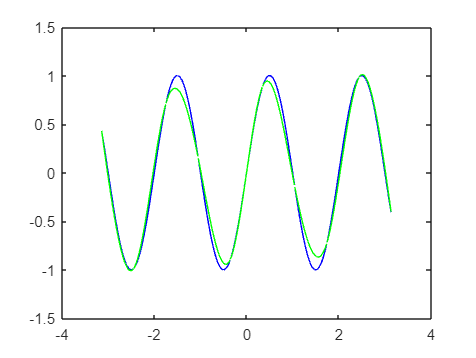

for i=1:n

    x = xi(i):0.01:xi(i+1);
    plot(x,f(x),'b')
    hold on 
    plot(x,ai(i)+bi(i).*(x-xi(i))+ci(i).*(x-xi(i)).^2+di(i).*(x-xi(i)).^3 ,'g')

end